## Example #1

### Isotropic random sampling

fctn_x = @(u,v)sin(u).*cos(v);
fctn_y = @(u,v)sin(u).*sin(v);
fctn_z = @(u,v)cos(u);

range_u = [0 pi 20];    % latitude angle for a sphere
range_v = [0 2*pi 40]; % longitude angle for a sphere

[M1, u1, v1] = sphere_homeo_sfc_isotropic_splg(fctn_x, fctn_y, fctn_z, range_u, range_v);

Random sampling option selected by default.


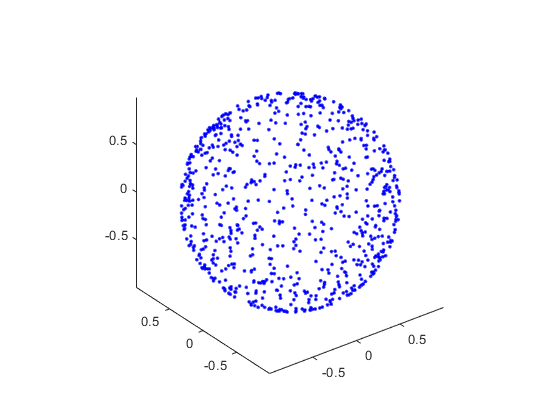

figure;
plot3(M1(:,1), M1(:,2), M1(:,3), 'b.'), hold on;
axis equal, axis square, axis tight;
colormap([0 0 1]);

## Example #2

### Isotropic regular sampling

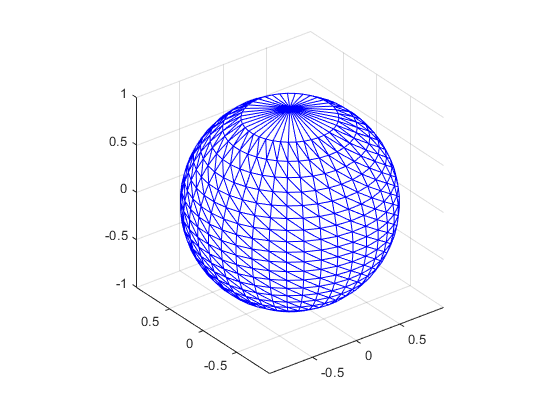

[M2, u2, v2, T] = sphere_homeo_sfc_isotropic_splg(fctn_x, fctn_y, fctn_z, range_u, range_v, 0);
TRI = triangulation(T, M2(:,1), M2(:,2), M2(:,3));

figure;
trimesh(TRI), hold on;
axis equal, axis square, axis tight;
colormap([0 0 1]);